clc,clear;
%iosr.dsp.ltas command from Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.
%Pop 80s

[P1,fs]=audioread("Call me.wav");
[P2,fs]=audioread("Another Brick In The Wall (Part II).wav");
[P3,fs]=audioread("A Woman in Love.wav");
[P4,fs]=audioread("(Just Like) Starting Over.wav");
[P5,fs]=audioread("Upside Down.wav");
[P6,fs]=audioread("The Winner Takes It All.wav");
[P7,fs]=audioread("Super Trouper.wav");
[P8,fs]=audioread("It's a Real Good Feeling.wav");
[P9,fs]=audioread("Sun of Jamaica.wav");
[P10,fs]=audioread("Xanadu.wav");
[P11,fs]=audioread("Shining Star.wav");
[P12,fs]=audioread("Take On Me.wav");
[P13,fs]=audioread("Never Gonna Give You Up.wav");
[P14,fs]=audioread("Brother Louie.wav");
[P15,fs]=audioread("I Wanna Dance with Somebody (Who Loves Me).wav");
[P16,fs]=audioread("I'm still standing.wav");
[P17,fs]=audioread("The Way You Make Me Feel.wav");
[P18,fs]=audioread("Wake Me Up Before You Go-Go.wav");
[P19,fs]=audioread("Big in Japan.wav");
[P20,fs]=audioread("You Win Again.wav");



figure
[S1,F]=iosr.dsp.ltas(P1,fs,'noct',6,'graph',true,'units','dB');
hold on;
[S2,F]=iosr.dsp.ltas(P2,fs,'noct',6,'graph',false,'units','dB');
[S3,F]=iosr.dsp.ltas(P3,fs,'noct',6,'graph',false,'units','dB');
[S4,F]=iosr.dsp.ltas(P4,fs,'noct',6,'graph',false,'units','dB');
[S5,F]=iosr.dsp.ltas(P5,fs,'noct',6,'graph',false,'units','dB');
[S6,F]=iosr.dsp.ltas(P6,fs,'noct',6,'graph',false,'units','dB');
[S7,F]=iosr.dsp.ltas(P7,fs,'noct',6,'graph',false,'units','dB');
[S8,F]=iosr.dsp.ltas(P8,fs,'noct',6,'graph',false,'units','dB');
[S9,F]=iosr.dsp.ltas(P9,fs,'noct',6,'graph',false,'units','dB');
[S10,F]=iosr.dsp.ltas(P10,fs,'noct',6,'graph',false,'units','dB');
[S11,F]=iosr.dsp.ltas(P11,fs,'noct',6,'graph',false,'units','dB');
[S12,F]=iosr.dsp.ltas(P12,fs,'noct',6,'graph',false,'units','dB');
[S13,F]=iosr.dsp.ltas(P13,fs,'noct',6,'graph',false,'units','dB');
[S14,F]=iosr.dsp.ltas(P14,fs,'noct',6,'graph',false,'units','dB');
[S15,F]=iosr.dsp.ltas(P15,fs,'noct',6,'graph',false,'units','dB');
[S16,F]=iosr.dsp.ltas(P16,fs,'noct',6,'graph',false,'units','dB');
[S17,F]=iosr.dsp.ltas(P17,fs,'noct',6,'graph',false,'units','dB');
[S18,F]=iosr.dsp.ltas(P18,fs,'noct',6,'graph',false,'units','dB');
[S19,F]=iosr.dsp.ltas(P19,fs,'noct',6,'graph',false,'units','dB');
[S20,F]=iosr.dsp.ltas(P20,fs,'noct',6,'graph',false,'units','dB');



S=[S1(:), S2(:),S3(:),S4(:),S5(:),S6(:),S7(:),S8(:),S9(:),S10(:),S11(:),S12(:),S13(:),S14(:),S15(:),S16(:),S17(:),S18(:),S19(:),S20(:)];
S=S.';
MS=mean(S);




%plot(F,MS,LineWidth=2,Color='r');

%Source for plot function
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.
hold on;
MS=MS.'

MS =   -60.0794
  -59.1495
  -53.4225
  -43.0925
  -36.1416
  -33.3881
  -33.2312
  -33.8884
  -34.5417
  -35.6760


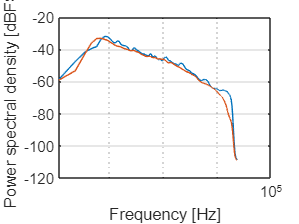

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MS);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MS,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(F,rearrange(MS,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end




%Pop 2000s


[P21,fz]=audioread("Poker Face.wav");
[P22,fz]=audioread("Music.wav");
[P23,fz]=audioread("Oops!... I Did It Again.wav");
[P24,fz]=audioread("It's Gonna Be Me.wav");
[P25,fz]=audioread("Liquid Dreams.wav");
[P26,fz]=audioread("Gotta Tell You.wav");
[P27,fz]=audioread("I Gotta Feeling.wav");
[P28,fz]=audioread("Shape of My Heart.wav");
[P29,fz]=audioread("4 Minutes.wav");
[P30,fz]=audioread("Bleeding Love.wav");
[P31,fz]=audioread("Hips don't lie.wav");
[P32,fz]=audioread("Can't get you out of my head.wav");
[P33,fz]=audioread("Hot n Cold.wav");
[P34,fz]=audioread("I kissed a Girl.wav");
[P35,fz]=audioread("Womanizer.wav");
[P36,fz]=audioread("Don't Stop the Music.wav");
[P37,fz]=audioread("Hung up.wav");
[P38,fz]=audioread("Single Ladies (Put a Ring on it).wav");
[P39,fz]=audioread("Doesn't Really Matter.wav");
[P40,fz]=audioread("I belong to you.wav");

figure
[PP1,FZ]=iosr.dsp.ltas(P21,fz,'noct',6,'graph',true,'units','dB');
hold on;
[PP2,FZ]=iosr.dsp.ltas(P22,fz,'noct',6,'graph',false,'units','dB');
[PP3,FZ]=iosr.dsp.ltas(P23,fz,'noct',6,'graph',false,'units','dB');
[PP4,FZ]=iosr.dsp.ltas(P24,fz,'noct',6,'graph',false,'units','dB');
[PP5,FZ]=iosr.dsp.ltas(P25,fz,'noct',6,'graph',false,'units','dB');
[PP6,FZ]=iosr.dsp.ltas(P26,fz,'noct',6,'graph',false,'units','dB');
[PP7,FZ]=iosr.dsp.ltas(P27,fz,'noct',6,'graph',false,'units','dB');
[PP8,FZ]=iosr.dsp.ltas(P28,fz,'noct',6,'graph',false,'units','dB');
[PP9,FZ]=iosr.dsp.ltas(P29,fz,'noct',6,'graph',false,'units','dB');
[PP10,FZ]=iosr.dsp.ltas(P30,fz,'noct',6,'graph',false,'units','dB');
[PP11,FZ]=iosr.dsp.ltas(P31,fz,'noct',6,'graph',false,'units','dB');
[PP12,FZ]=iosr.dsp.ltas(P32,fz,'noct',6,'graph',false,'units','dB');
[PP13,FZ]=iosr.dsp.ltas(P33,fz,'noct',6,'graph',false,'units','dB');
[PP14,FZ]=iosr.dsp.ltas(P34,fz,'noct',6,'graph',false,'units','dB');
[PP15,FZ]=iosr.dsp.ltas(P35,fz,'noct',6,'graph',false,'units','dB');
[PP16,FZ]=iosr.dsp.ltas(P36,fz,'noct',6,'graph',false,'units','dB');
[PP17,FZ]=iosr.dsp.ltas(P37,fz,'noct',6,'graph',false,'units','dB');
[PP18,FZ]=iosr.dsp.ltas(P38,fz,'noct',6,'graph',false,'units','dB');
[PP19,FZ]=iosr.dsp.ltas(P39,fz,'noct',6,'graph',false,'units','dB');
[PP20,FZ]=iosr.dsp.ltas(P40,fz,'noct',6,'graph',false,'units','dB');



P2000=[PP1(:), PP2(:),PP3(:),PP4(:),PP5(:),PP6(:),PP7(:),PP8(:),PP9(:),PP10(:),PP11(:),PP12(:),PP13(:),PP14(:),PP15(:),PP16(:),PP17(:),PP18(:),PP19(:),PP20(:)];
P2000=P2000.';
MP2000=mean(P2000);




plot(FZ,MP2000,LineWidth=2,Color='r');

%Source for plot function
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.
hold on;
MP2000=MP2000.'

MP2000 =   -54.6034
  -49.6728
  -43.6798
  -36.1799
  -29.9565
  -29.2719
  -31.4990
  -33.1376
  -34.0641
  -34.6663


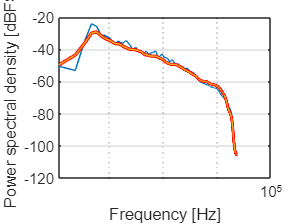

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2000);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2000,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FZ,rearrange(MP2000,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end

%Pop 2020s


[P41,fq]=audioread("Rudebox.wav");
[P42,fq]=audioread("Don't Stop Now.wav");
[P43,fq]=audioread("Physical.wav");
[P44,fq]=audioread("Blinding Lights.wav");
[P45,fq]=audioread("Intentions.wav");
[P46,fq]=audioread("Yummy.wav");
[P47,fq]=audioread("Bad Habits.wav");
[P48,fq]=audioread("Stupid Love.wav");
[P49,fq]=audioread("Easy On Me.wav");
[P50,fq]=audioread("Midnight Sky.wav");
[P51,fq]=audioread("Arcade.wav");
[P52,fq]=audioread("Lose You To Love Me.wav");
[P53,fq]=audioread("Say So.wav");
[P54,fq]=audioread("Oh My God.wav");
[P55,fq]=audioread("What a man gotta do.wav");
[P56,fq]=audioread("People I've been sad (Together at Home).wav");
[P57,fq]=audioread("Flowers.wav");
[P58,fq]=audioread("Eyes Closed.wav");
[P59,fq]=audioread("Kings & Queens.wav");
[P60,fq]=audioread("Save Your Tears.wav");

figure
[Q1,FQ]=iosr.dsp.ltas(P41,fq,'noct',6,'graph',true,'units','dB');
hold on;
[Q2,FQ]=iosr.dsp.ltas(P42,fq,'noct',6,'graph',false,'units','dB');
[Q3,FQ]=iosr.dsp.ltas(P43,fq,'noct',6,'graph',false,'units','dB');
[Q4,FQ]=iosr.dsp.ltas(P44,fq,'noct',6,'graph',false,'units','dB');
[Q5,FQ]=iosr.dsp.ltas(P45,fq,'noct',6,'graph',false,'units','dB');
[Q6,FQ]=iosr.dsp.ltas(P46,fq,'noct',6,'graph',false,'units','dB');
[Q7,FQ]=iosr.dsp.ltas(P47,fq,'noct',6,'graph',false,'units','dB');
[Q8,FQ]=iosr.dsp.ltas(P48,fq,'noct',6,'graph',false,'units','dB');
[Q9,FQ]=iosr.dsp.ltas(P49,fq,'noct',6,'graph',false,'units','dB');
[Q10,FQ]=iosr.dsp.ltas(P50,fq,'noct',6,'graph',false,'units','dB');
[Q11,FQ]=iosr.dsp.ltas(P51,fq,'noct',6,'graph',false,'units','dB');
[Q12,FQ]=iosr.dsp.ltas(P52,fq,'noct',6,'graph',false,'units','dB');
[Q13,FQ]=iosr.dsp.ltas(P53,fq,'noct',6,'graph',false,'units','dB');
[Q14,FQ]=iosr.dsp.ltas(P54,fq,'noct',6,'graph',false,'units','dB');
[Q15,FQ]=iosr.dsp.ltas(P55,fq,'noct',6,'graph',false,'units','dB');
[Q16,FQ]=iosr.dsp.ltas(P56,fq,'noct',6,'graph',false,'units','dB');
[Q17,FQ]=iosr.dsp.ltas(P57,fq,'noct',6,'graph',false,'units','dB');
[Q18,FQ]=iosr.dsp.ltas(P58,fq,'noct',6,'graph',false,'units','dB');
[Q19,FQ]=iosr.dsp.ltas(P59,fq,'noct',6,'graph',false,'units','dB');
[Q20,FQ]=iosr.dsp.ltas(P50,fq,'noct',6,'graph',false,'units','dB');

P2020=[Q1(:), Q2(:),Q3(:),Q4(:),Q5(:),Q6(:),Q7(:),Q8(:),Q9(:),Q10(:),Q11(:),Q12(:),Q13(:),Q14(:),Q15(:),Q16(:),Q17(:),Q18(:),Q19(:),Q20(:)];
P2020=P2020.';
MP2020=mean(P2020);




plot(FQ,MP2020,LineWidth=2,Color='r');

%Source for plot function
%Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.
hold on;
MP2020=MP2020.'

MP2020 =   -53.9247
  -51.1505
  -40.8597
  -31.6153
  -27.5258
  -27.1664
  -29.3883
  -31.0222
  -31.9374
  -32.0666


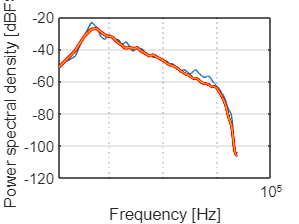

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2020);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2020,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FQ,rearrange(MP2020,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end



figure()
%legend('Pop 2020s','Pop 2000s', 'Pop 80s')
MP2020=MP2020.'

MP2020 =   -53.9247  -51.1505  -40.8597  -31.6153  -27.5258  -27.1664  -29.3883  -31.0222  -31.9374  -32.0666  -32.7841  -34.2820  -35.5321  -36.3401  -36.9626  -37.9219  -38.8444  -39.3087  -39.2453  -39.1267  -39.0841  -39.0254  -39.2180  -39.4801  -39.5719  -39.5730  -39.4576  -39.1604  -38.9760  -39.1805  -39.6534  -40.1679  -40.6585  -41.1288  -41.5096  -41.7139  -41.7961  -41.9330  -42.2109  -42.5302  -42.7557  -42.8831  -43.0175  -43.2402  -43.5336  -43.8150  -44.0116  -44.1074  -44.1382  -44.1525


NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2020);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2020,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FQ,rearrange(MP2020,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end


hold on;
MP2000=MP2000.'

MP2000 =   -54.6034  -49.6728  -43.6798  -36.1799  -29.9565  -29.2719  -31.4990  -33.1376  -34.0641  -34.6663  -35.8200  -36.6205  -36.6105  -36.6644  -37.2654  -37.9307  -38.4928  -38.8319  -39.1777  -39.5970  -39.9529  -40.0628  -40.0858  -40.1963  -40.2556  -40.2753  -40.3711  -40.4943  -40.6350  -40.8498  -41.1032  -41.2844  -41.3713  -41.4826  -41.7177  -42.0435  -42.3846  -42.7212  -43.0537  -43.3426  -43.5312  -43.6027  -43.5982  -43.5888  -43.6328  -43.7429  -43.8841  -44.0067  -44.0855  -44.1323


NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MP2000);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MP2000,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(FZ,rearrange(MP2000,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end


hold on;
MS=MS.'

MS =   -60.0794  -59.1495  -53.4225  -43.0925  -36.1416  -33.3881  -33.2312  -33.8884  -34.5417  -35.6760  -36.6481  -37.6323  -38.1532  -38.3015  -38.5863  -39.0522  -39.5261  -39.8155  -40.0077  -40.2424  -40.6639  -40.9506  -40.9035  -40.7377  -40.6819  -40.8467  -41.1787  -41.4683  -41.6242  -41.7570  -41.9997  -42.3523  -42.7131  -43.0160  -43.2607  -43.4506  -43.5899  -43.7150  -43.8710  -44.0675  -44.2751  -44.4505  -44.5585  -44.5861  -44.5481  -44.4776  -44.4088  -44.3657  -44.3657  -44.4234


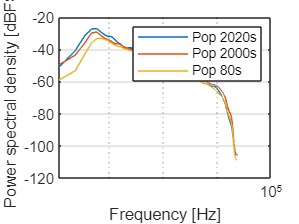

NFFT = 4096;
win = NFFT;
hop=NFFT/2;

dims = size(MS);
dim = find(dims>1,1,'first');
if mod(NFFT,2)==0
        Nout = (NFFT/2)+1;
    else
        Nout = (NFFT+1)/2;
    end
order = mod(dim-1:dim+length(dims)-2,length(dims))+1;
dims_shift = dims(order);
x = rearrange(MS,order,[dims_shift(1) prod(dims_shift(2:end))]);
dims_out_shift = dims_shift;
dims_out_shift(1) = Nout;
units = @(x) 10*log10(x);
max0scale = @(s) s-max(s(:));
labelY = 'Power spectral density [dBFS]';
yscale = 'linear';



semilogx(F,rearrange(MS,order,[dims_out_shift(1) prod(dims_out_shift(2:end))]));
xlabel('Frequency [Hz]');
ylabel(labelY);
set(gca,'yscale',yscale);
grid on

if prod(dims_out_shift(2:end)) > 1
   legend(num2str((1:prod(dims_out_shift(2:end)))'));
end

hold on
legend('Pop 2020s', 'Pop 2000s', 'Pop 80s')
%plot(FZ,MP2000,LineWidth=2,Color='r');
hold off

function y = rearrange(x,order,shape)
%REARRANGE reshape and permute to make target dim column
    y = permute(x,order);
    y = reshape(y,shape);
end

function y = irearrange(x,order,shape)
%IREARRANGE reshape and permute to original size
    y = reshape(x,shape);
    y = ipermute(y,order);
end
%Functions from
% Christopher Hummersone (2023). Long term average spectrum (https://github.com/IoSR-Surrey/MatlabToolbox), GitHub. Retrieved February 22, 2023.

`The MIT License (MIT)`

`Copyright (c) 2016 Institute of Sound Recording`

`Permission is hereby granted, free of charge, to any person obtaining a copy`

`of this software and associated documentation files (the "Software"), to deal`

`in the Software without restriction, including without limitation the rights`

`to use, copy, modify, merge, publish, distribute, sublicense, and/or sell`

`copies of the Software, and to permit persons to whom the Software is`

`furnished to do so, subject to the following conditions:`

`The above copyright notice and this permission notice shall be included in all`

`copies or substantial portions of the Software.`

`THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR`

`IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,`

`FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE`

`AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER`

`LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,`

`OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE`

`SOFTWARE.`